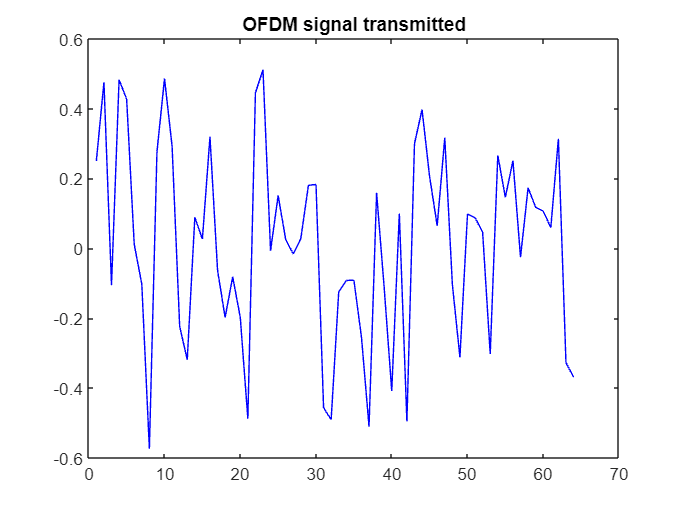

close all;
clear all;
clc;
n = 256;
x = randi ([0, 1], n, 1);
M = 16;
k = log2(M);
xsym = bi2de(reshape(x, k, length(x) / k).', 'left-msb');
y = qammod(xsym, M);

tu = 3.2e-6;
tg = 0.8e-6;
ts = tu+tg;
nmin = 0;
nmax = 64;
scb = 312.5e3;
fc = 3.6e9;
Rs = fc;
tt = 0:6.25e-8:ts-6.25e-8;

c = ifft (y, nmax);
s = real (c.'.*(exp(1j*2*pi*fc*tt)));

figure;
plot(real(s), 'b');
title('OFDM signal transmitted');

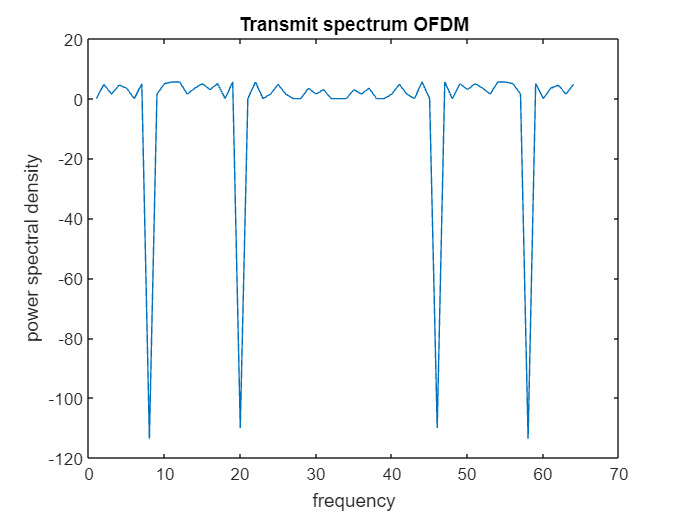


figure;
plot (10*log10(abs (fft(s, nmax)))); 
title('OFDM spectrum');
xlabel('frequency');
ylabel('power spectral density');
title('Transmit spectrum OFDM');

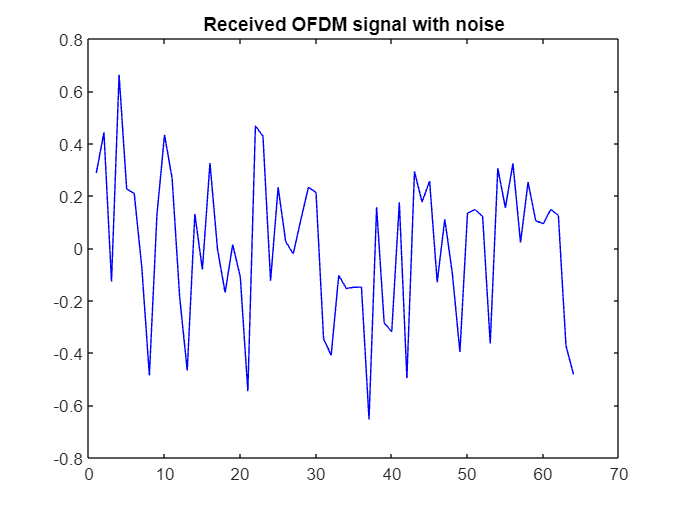


snr= 10;
ynoisy= awgn(s, snr, 'measured');
figure;
plot (real (ynoisy), 'b');
title('Received OFDM signal with noise');

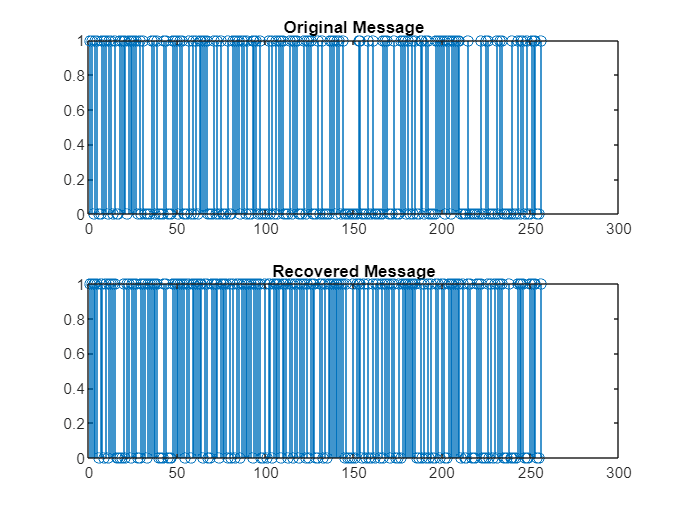


z=  ynoisy .* exp(1j*2*pi*fc*tt);
z = fft (z, nmax);
zsym= qamdemod(z, M);
z = de2bi(zsym, k, 'left-msb');
z = reshape(z.',prod(size(z)), 1);

[noe, ber]= biterr(x, z);

figure;
subplot(211);
stem(x(1:256));
title('Original Message');
subplot(212);
stem(z(1:256));
title('Recovered Message');